# Trabajo grupal 2 (Métodos Numéricos)

- Sección:

- N° de grupo: 

- Integrante 1 (líder):          

- Integrante 2:

- Integrante 3: Paula del Pilar Vértiz Puémape

- Integrante 4:

- Integrante 5:

**Observación:** No olvidar añadir el porcentaje de participación.

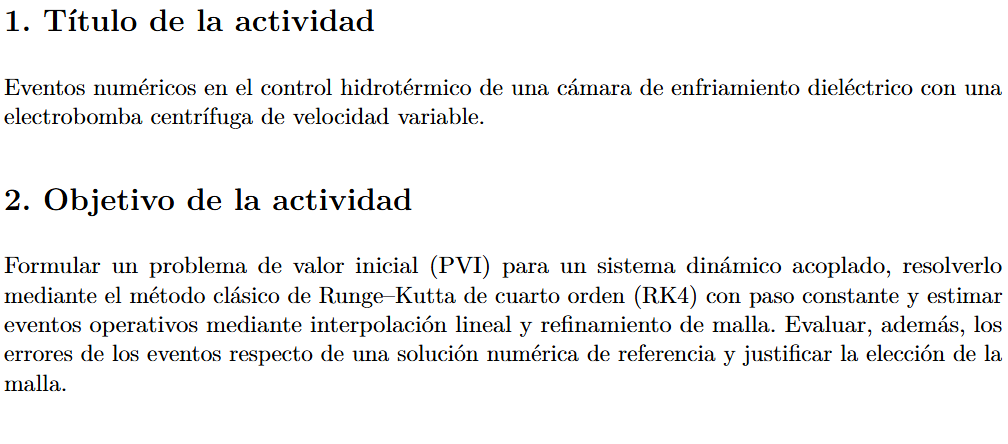

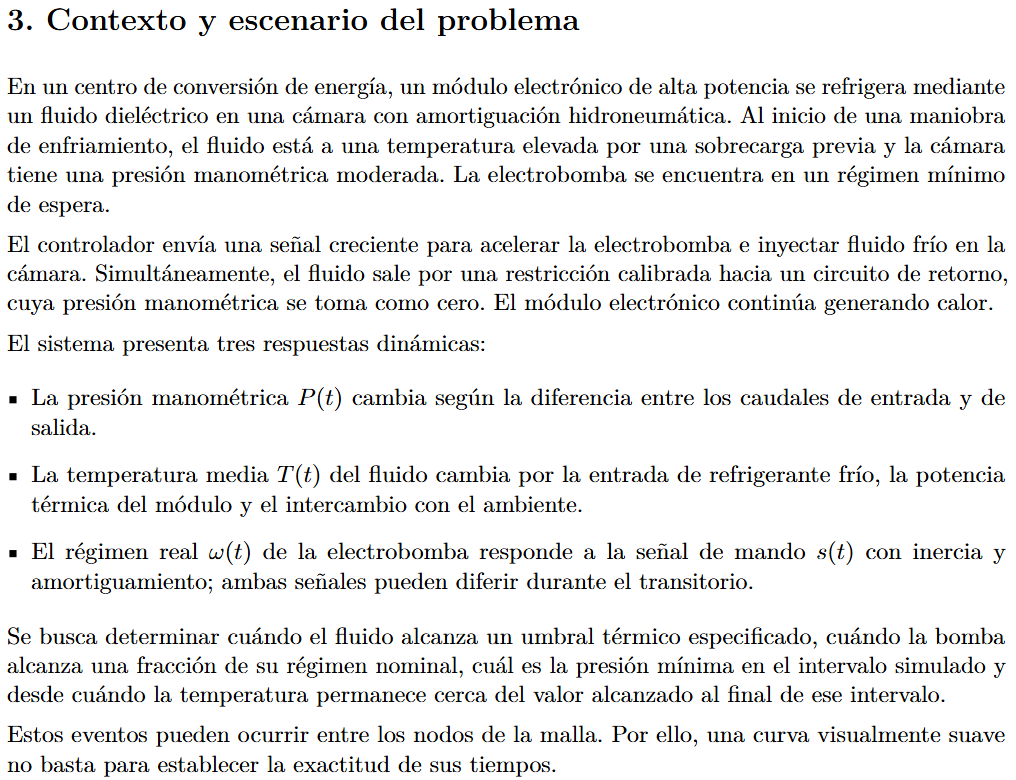

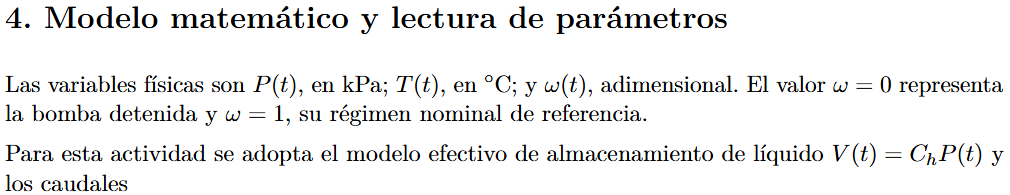

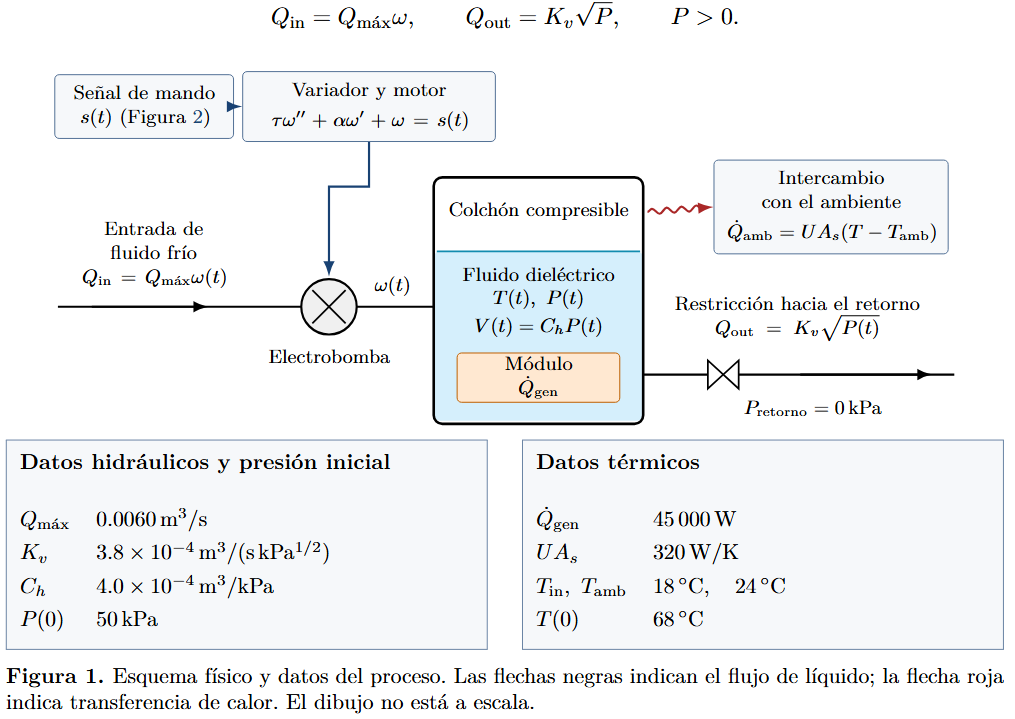

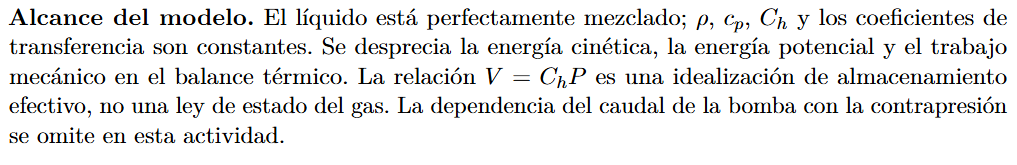

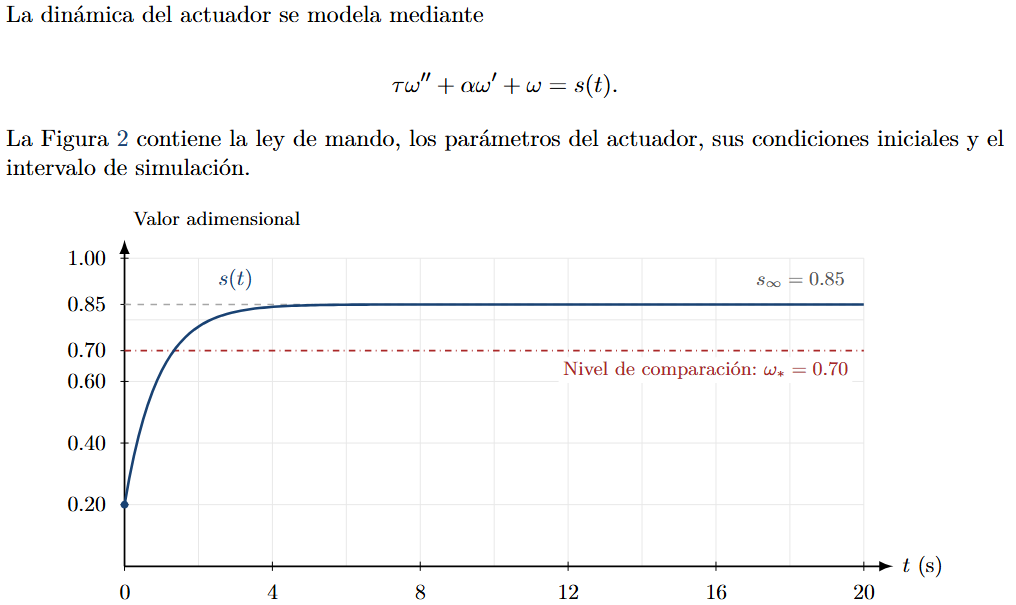

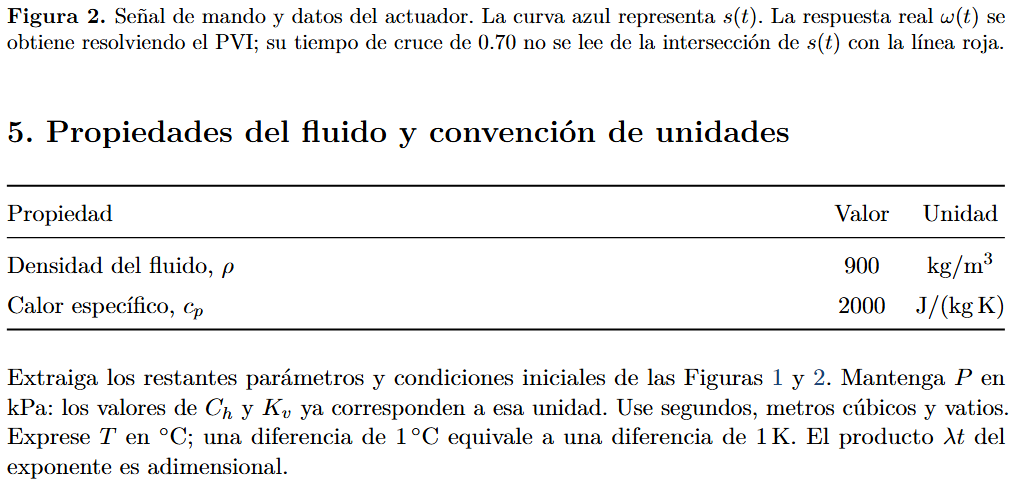

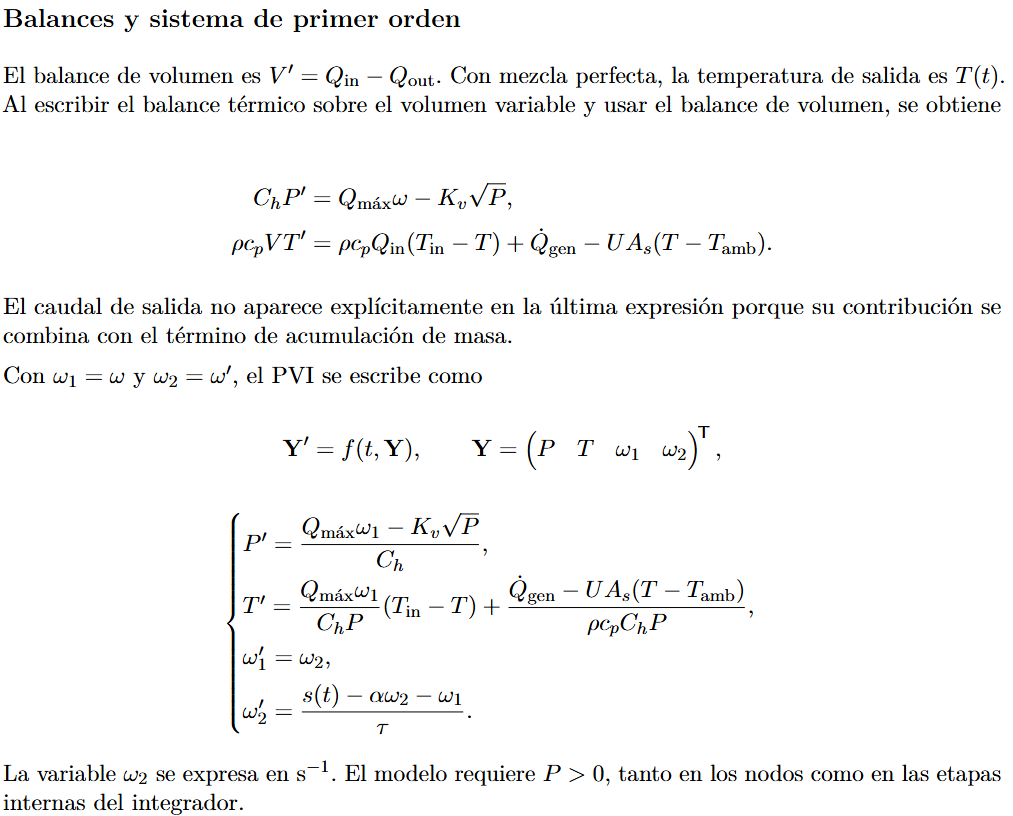

1. 


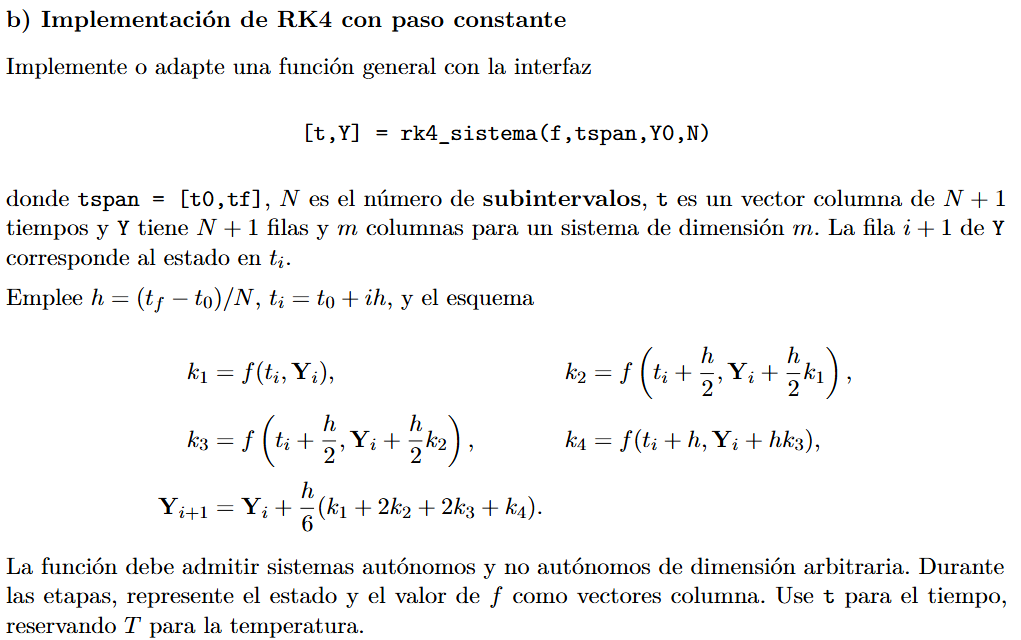

2. 


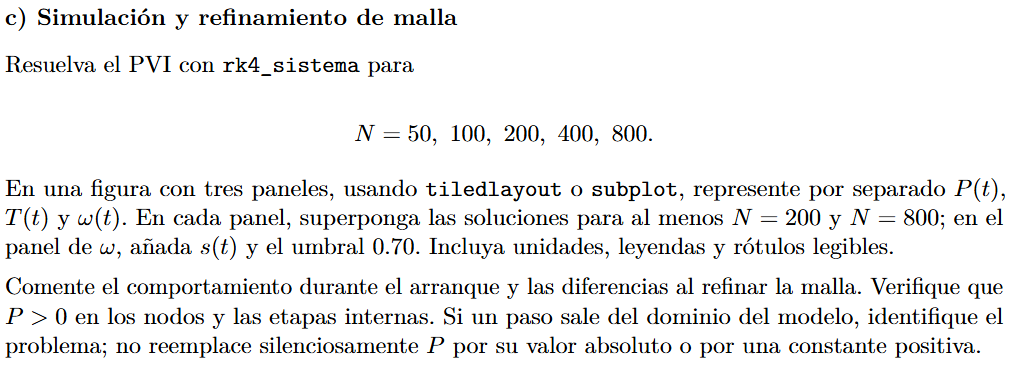

3.


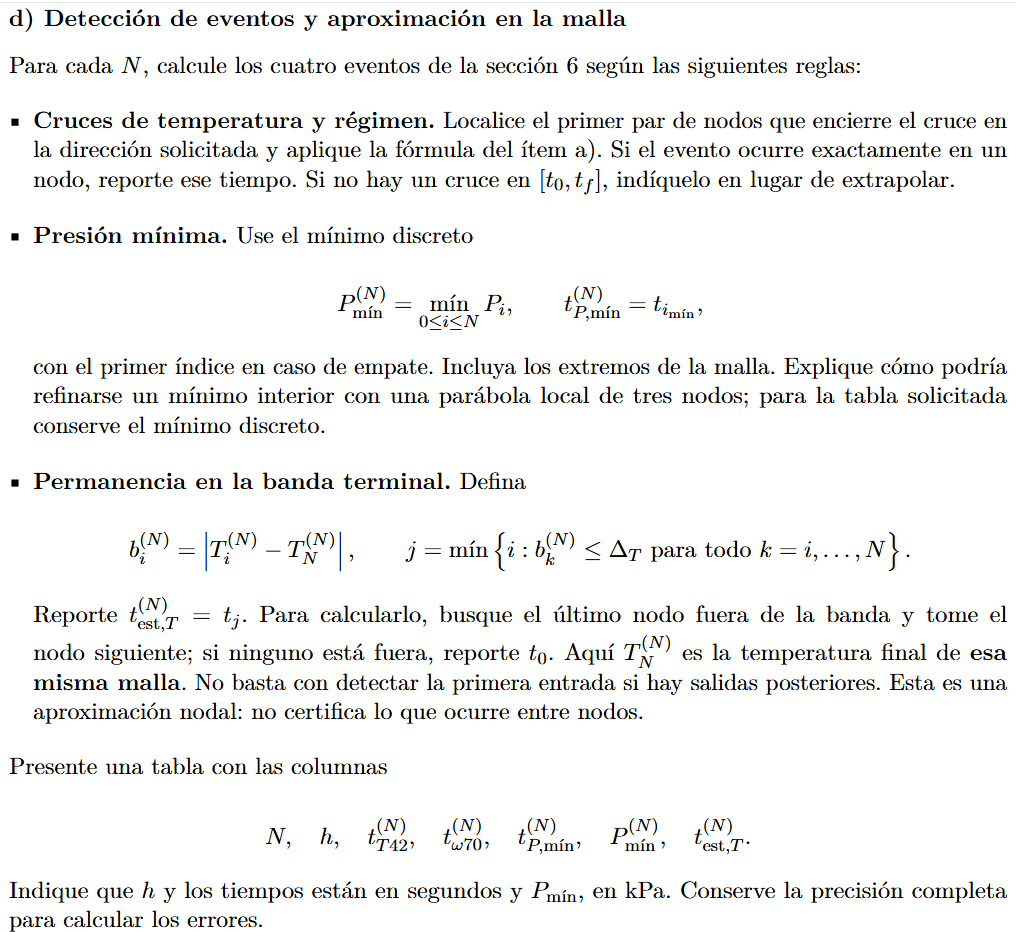

4.
nN   = numel(Ns);
hv   = (tf - t0)./Ns(:);              
tT42 = zeros(nN,1);  tw70 = zeros(nN,1);  tPmin = zeros(nN,1);
Pmn  = zeros(nN,1);  test = zeros(nN,1);

for j = 1:nN
    t = tN{j};  P = YN{j}(:,1);  T = YN{j}(:,2);  w = YN{j}(:,3);

    tT42(j) = cruce_lineal(t,T,Tumbral,'desc');  
    tw70(j) = cruce_lineal(t,w,wumbral,'asc');    

    [Pmn(j),imin] = min(P);                       
    tPmin(j) = t(imin);

    test(j) = t_estacionario(t,T,DT);            
end

tabla_d = table(Ns(:),hv,tT42,tw70,tPmin,Pmn,test, ...
    'VariableNames',{'N','h_s','t_T42_s','t_w70_s','t_Pmin_s','Pmin_kPa','t_est_T_s'});
tabla_d.Properties.VariableUnits = {'','s','s','s','s','kPa','s'};   

fprintf('Tabla del ítem d): h y los tiempos (t_T42, t_w70, t_Pmin, t_est_T) en segundos [s]; Pmin en kilopascales [kPa].\n');
format long g
disp(tabla_d)
format short

%Funciones auxiliares
function tev = cruce_lineal(t,y,ystar,dir)
tev = NaN;
d = y(:) - ystar;
if d(1) == 0                                   
    if (strcmp(dir,'desc') && d(2) < 0) || (strcmp(dir,'asc') && d(2) > 0)
        tev = t(1);  return
    end
end
for i = 1:numel(t)-1
    if strcmp(dir,'desc'), hay = d(i) > 0 && d(i+1) <= 0;
    else,                  hay = d(i) < 0 && d(i+1) >= 0;
    end
    if hay
        if d(i+1) == 0
            tev = t(i+1);                      
        else
            tev = t(i) + (ystar - y(i))/(y(i+1) - y(i))*(t(i+1) - t(i));
        end
        return
    end
end
end

function tj = t_estacionario(t,T,dT)
b = abs(T(:) - T(end));
fuera = find(b > dT, 1, 'last');              
if isempty(fuera), tj = t(1); else, tj = t(fuera+1); end
end

- Si el valor mínimo no está en los extremos, podemos mejorar su cálculo utilizando los tres puntos más cercanos. Para ello, se forma una parábola con esos puntos y se busca su punto más bajo. Así podemos obtener un valor más preciso del momento en que ocurre la presión mínima y cuánto vale.

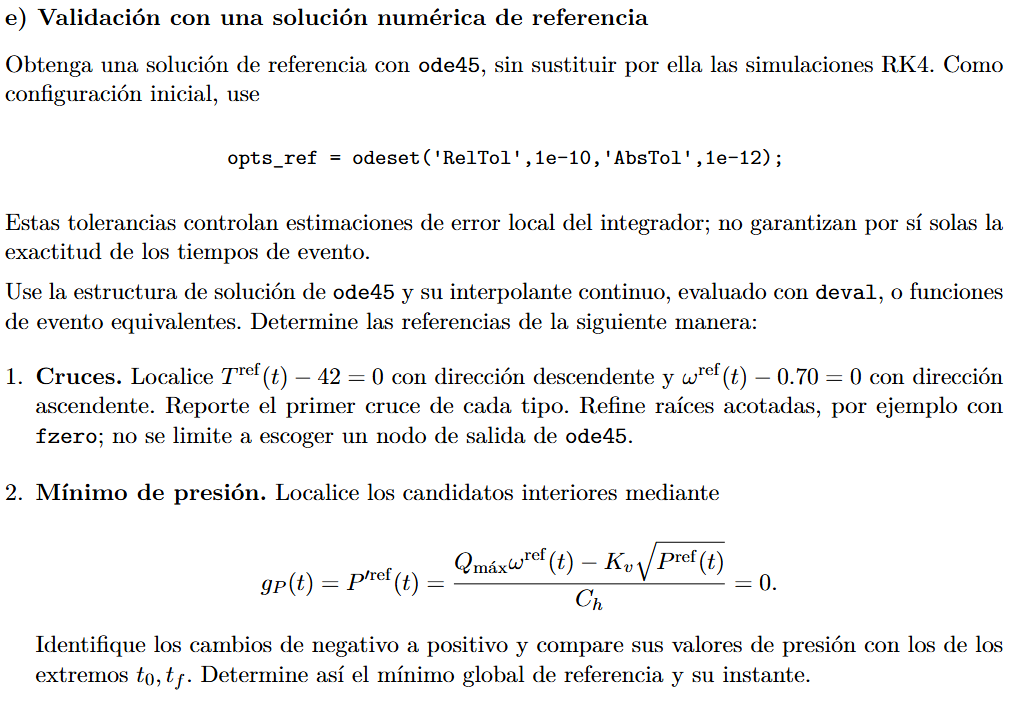

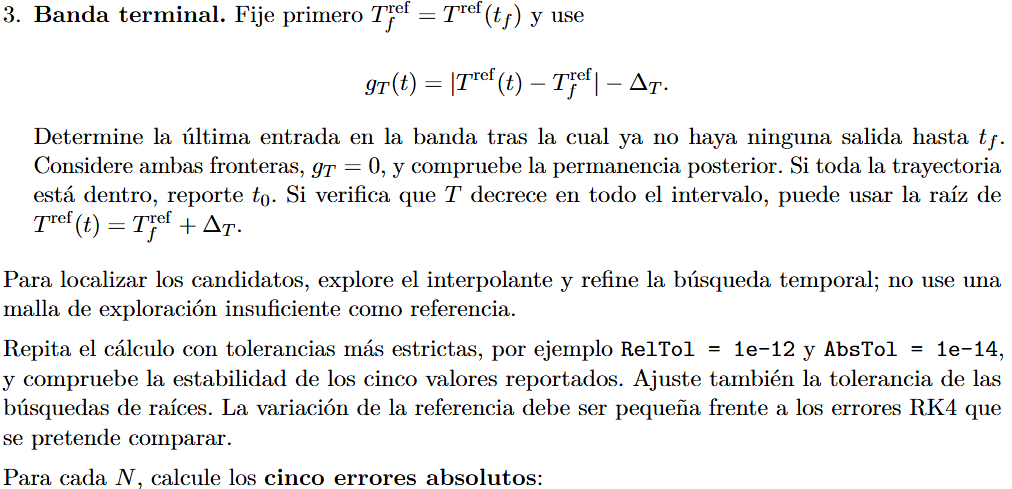

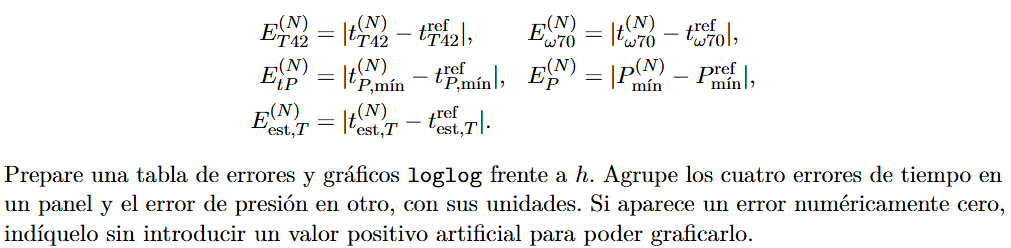

5.


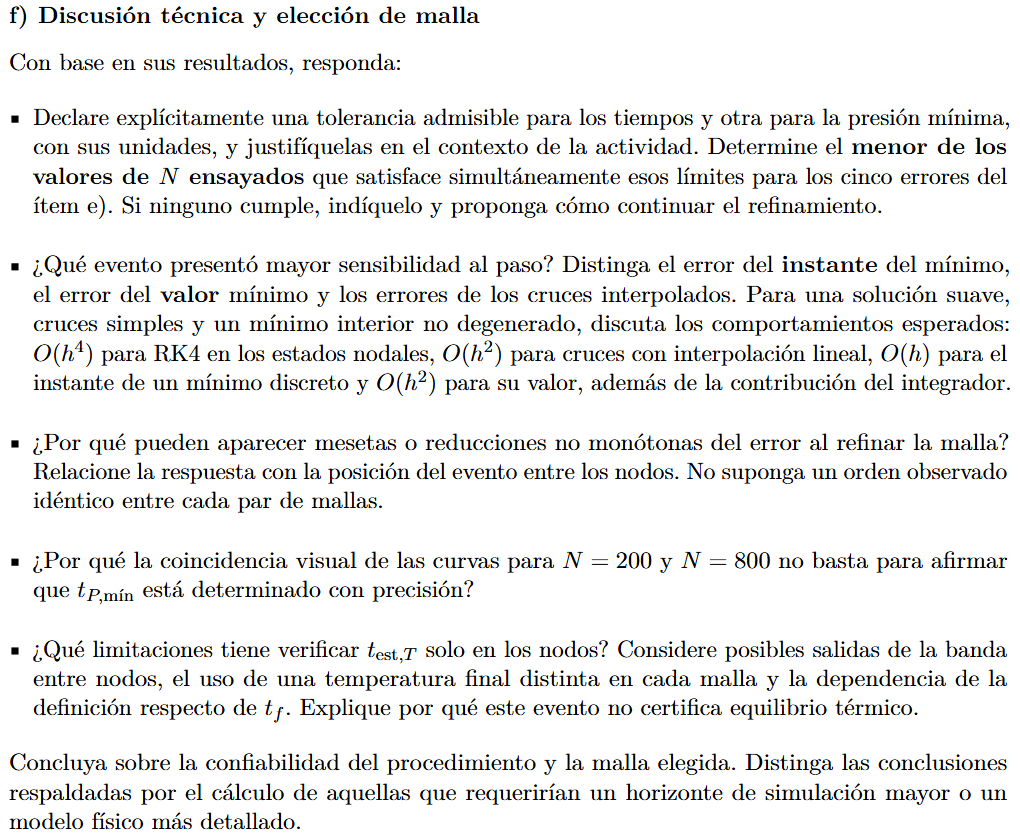

6.
